%_________________________________________________________________%
% ------------  Course          :      MIMO          ----------- %
% ------------  Student Name    :      Sohrab Rezaei    ----------- %
%                        Course project                          %
%                         L-Dominance                            %
%_____________________________________________________________________%
clc; clear; close all ;

s=tf('s');

## GT

G11=(0.806*s+0.264)/(s^2+1.15*s+0.202);
G12=-(15*s+1.42)/(s^3+12.8*s^2+13.6*s+2.36);
G21=(1.95*s^2+2.12*s+0.49)/(s^3+9.15*s^2+9.39*s+1.62);
G22=(7.14*s^2+25.8*s+9.35)/(s^4+20.8*s^3+116.4*s^2+111.6*s+18.8);
G=[G11,G12;G21,G22]


G =
 
  From input 1 to output...
         0.806 s + 0.264
   1:  --------------------
       s^2 + 1.15 s + 0.202
 
          1.95 s^2 + 2.12 s + 0.49
   2:  ------------------------------
       s^3 + 9.15 s^2 + 9.39 s + 1.62
 
  From input 2 to output...
                -15 s - 1.42
   1:  ------------------------------
       s^3 + 12.8 s^2 + 13.6 s + 2.36
 
                7.14 s^2 + 25.8 s + 9.35
   2:  -------------------------------------------
       s^4 + 20.8 s^3 + 116.4 s^2 + 111.6 s + 18.8
 
Continuous-time transfer function.


a11=[1 1.15 0.202];
a12=[1 12.8 13.6 2.36];
a21=[1 9.15 9.39 1.62];
a22=[1 20.8 116.4 111.6 18.8];

b11=[0.806 0.264];
b12=-[15 1.42];
b21=[1.95 2.12 0.49];
b22=[7.14 25.8 9.35];

## Gershgorin

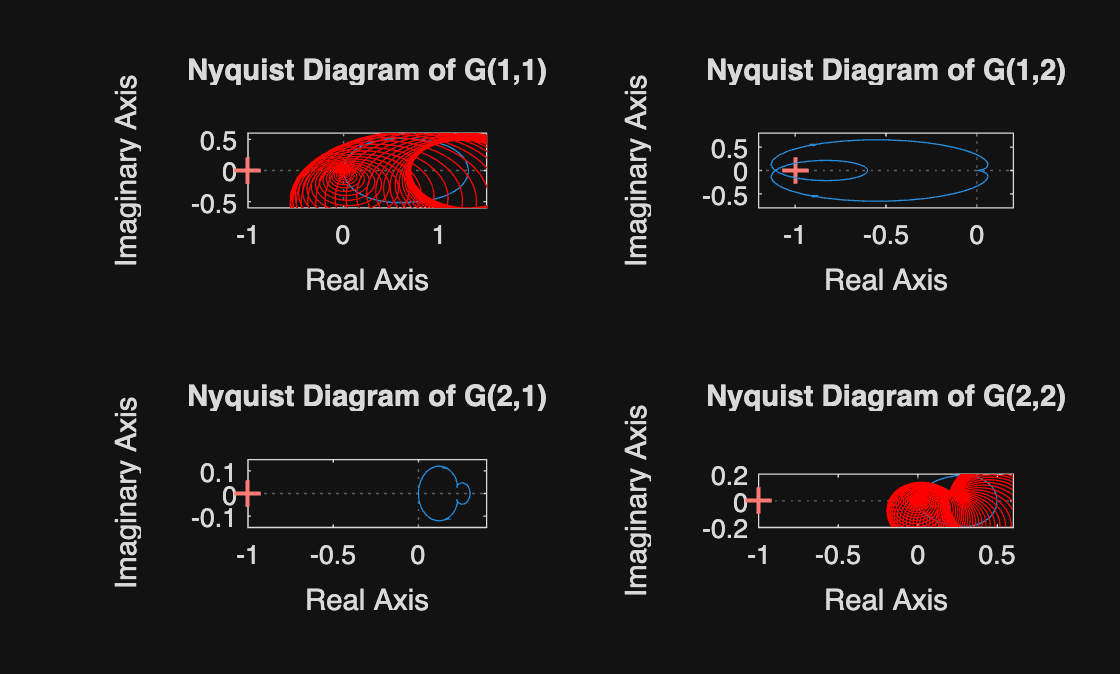

Gershgorinbands_MIMO(G)
saveas(gcf, 'gershgorin.fig');         % Save as MATLAB figure

saveas(gcf, 'gershgorin.fig');         % Save as MATLAB figure

## First Loop

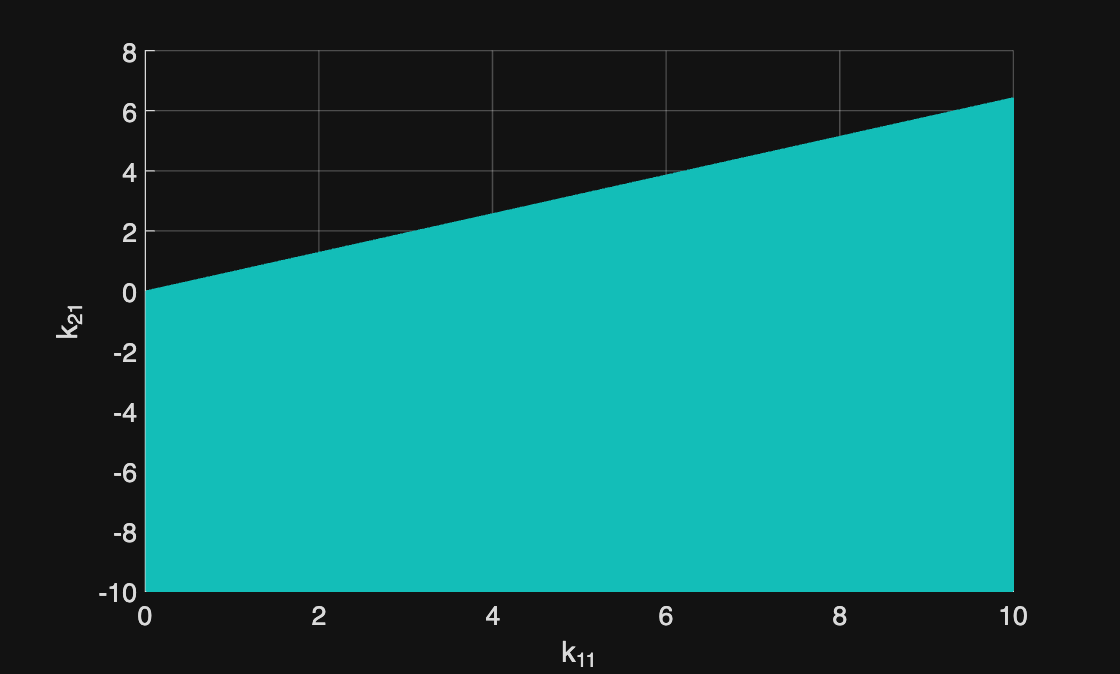

x=-10:0.01:10;
[x1,x2]=meshgrid(x);
I_1=0.806*x1>0;
I_2=10.5808*x1-15*x2>0;
I_3=147.3*x1.^2+280.05*x2.^2-408.8972*x1.*x2>0;
I_4=739.37*x1.^3-1241.34*x2.^3-2702.95*x1.^2.*x2+3213.68*x1.*x2.^2>0;
I_5=0.623*x1-0.2868*x2>0;
I_1=double(I_1); I_1(I_1==0)=NaN;
I_2=double(I_2); I_2(I_2==0)=NaN;
I_3=double(I_3); I_3(I_3==0)=NaN;
I_4=double(I_4); I_4(I_4==0)=NaN;
I_5=double(I_5); I_5(I_5==0)=NaN;
I=I_1.*I_2.*I_3.*I_4.*I_5;
figure()
surf(x1,x2,I,'EdgeColor','flat');
view(0,90)
xlabel('k_{11}')
ylabel('k_{21}')

saveas(gcf, 'K.fig');         % Save as MATLAB figure


## L-dominance

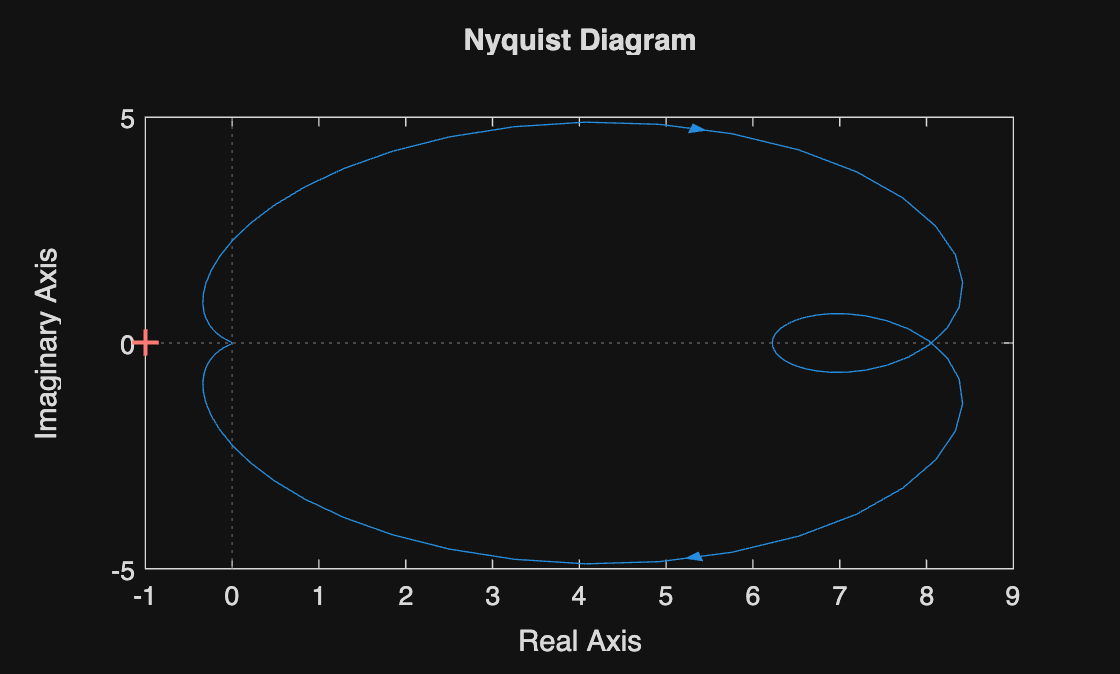



K=[2,2.5;-6,5.5];
Q11=K(1,1)*G11+K(2,1)*G12;
Q12=K(1,2)*G11+K(2,2)*G12;
Q21=K(1,1)*G21+K(2,1)*G22;
Q22=K(1,2)*G21+K(2,2)*G22;
Q=[Q11,Q12;Q21,Q22];

f1=1;
f2=1;
t11=(1/f1+Q11);
t12=(Q12);
t21=(Q21);
t22=(1/f2+Q22);
P_1=[1,0;-t21/t11,1];
L21=-t22/t11;
sigma_L=L21*t12;
figure()
nyquist(Q11)
saveas(gcf, 'G1LCir.fig');         % Save as MATLAB figure

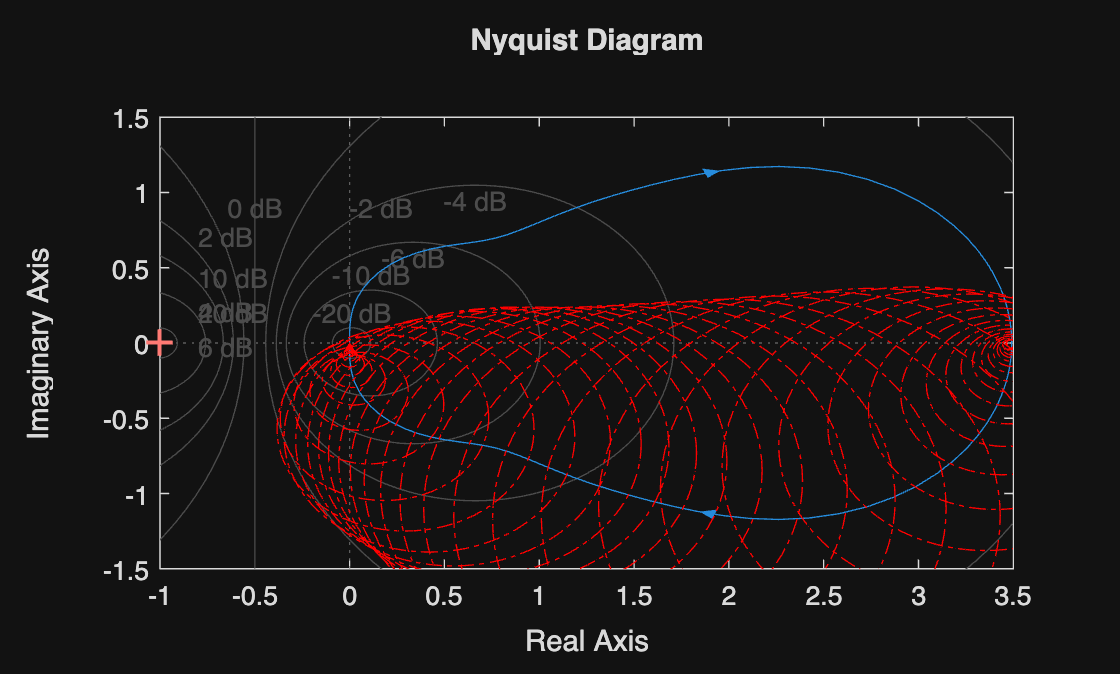



L_dominance_Circles(sigma_L,Q22)

saveas(gcf, 'G2LCir.fig');         % Save as MATLAB figure

## PI Controllers

C1=pidtune(t11,'pi');
C2=pidtune(t22,'pi');
P1=C1.Kp;
I1=C1.Ki;
D1=C1.Kd;
P2=C2.Kp;
I2=C2.Ki;
D2=C2.Kd;
L21=-t22/t11;
C=[C1,0;0,C2]


C =
 
  From input 1 to output...
       0.1807 s + 0.7815
   1:  -----------------
               s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       0.7251
   2:  ------
         s
 
Continuous-time transfer function.
